**Initialising the IMU object with default values**

imu = imuSensor("SampleRate", 1000)

imu =   imuSensor with properties:

          IMUType: 'accel-gyro'
       SampleRate: 1000
      Temperature: 25
    Accelerometer: [1×1 accelparams]
        Gyroscope: [1×1 gyroparams]
     RandomStream: 'Global stream'


**Setting up imu **

N = 5000;
acc = zeros(N,3);
angular_velocity = zeros(N,3);

[acc_stat, gyro_stat] = imu(acc,angular_velocity);

Fs = 1000;                      % samples per second
step = 1/Fs;                    % seconds per sample
StopTime = 5;                  % seconds
t = (0:step:((N-1)*step));      % seconds

**Plot stationary outputs**

% plot(t,acc_stat)
% legend('X-axis','Y-axis','Z-axis')
% title('Accelerometer Readings')
% ylabel('Acceleration (m/s^2)') 
% 
% xlim([0.000 1.000])
% ylim([-1 10.00])
% 
% plot(t,gyro_stat)
% legend('X-axis','Y-axis','Z-axis')
% title('Gyroscope Readings')
% ylabel('Angular rate (rad/s)')

**Accelerometer and Gyro axis inputs **

% Testing with sinusodial input on X and Y axis of
% accelerometer and gyroscope
fc = 20;
acc(:,1) = 0.5*sin(30*t);
acc(:,2) = 1*sin(20*t);
acc(:,3) = 0.7*sin(15*t);


angular_velocity(:,1) = sin(2*pi*fc*t);
[acc_test, gyro_test] = imu(acc,angular_velocity);

%break up acceleration array into its components
ax = acc_test(:,1);
ay = acc_test(:,2);
az = acc_test(:,3);

%break up gyroscope array into its components
gx = gyro_test(:,1);
gy = gyro_test(:,2);
gz = gyro_test(:,3);

%Perform gyro integration to get the euler angles
roll = cumtrapz(t,gx);
pitch = cumtrapz(t,gy);
yaw = cumtrapz(t,gz); 

**Rotations to inertial axis**

% %Perform rotation 
% syms theta phi psi ex ey ez filter 'real'
% 
% rx = [1 0 0;0 cos(phi) sin(phi); 0 -sin(phi) cos(phi)]
% ry = [cos(theta) 0 -sin(theta); 0 1 0;sin(theta) 0 cos(theta)]
% rz = [cos(psi) sin(psi) 0; -sin(psi) cos(psi) 0; 0 0 1] 
% 
% rotations = rx*ry'*rz 
% inverse_rot = inv(rz)*inv(ry)*inv(rx);
% inverse_rot = simplify(inverse_rot) 
% 
% inverse_rot = double(subs(inverse_rot, [phi,theta,psi], [roll,pitch,yaw]));

**Acceleration calculation ( inertial frame )**

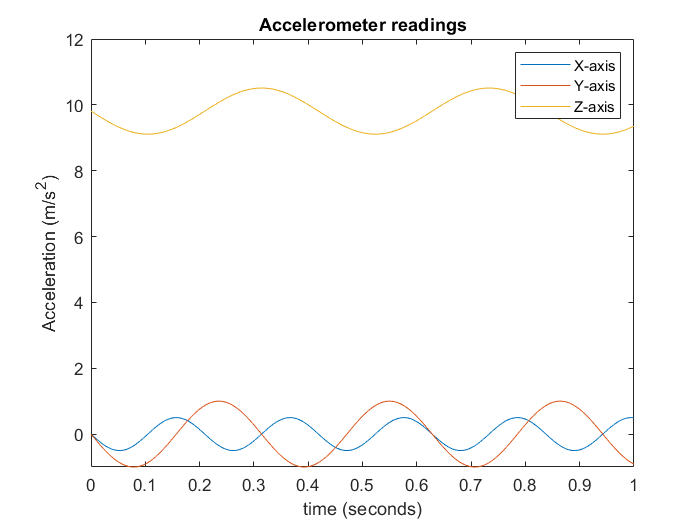

% acc_matrix = inverse_rot*[ax;ay;az] - [0;0;g];
% Az = simplify(acc_matrix(3,:));

%match euler angles to Acceleration 
phi = roll;
theta = pitch;

%update angles such that we get negative cycle included
phi = phi - max(roll)/2;
theta = theta - max(pitch)/2;

%gravity term
g = 9.81 * ones(N,1); 

%Perform rotation to inertial axis
%Az = -ax.*sin(theta) + ay.*cos(theta).*sin(phi) + az.*cos(phi).*cos(theta) - g

%add height measurements from each axis
Az_x = acc_test(:,1); 
Az_y = acc_test(:,2); 
Az_z = acc_test(:,3); 

plot(t,acc_test)
legend('X-axis','Y-axis','Z-axis')
title('Accelerometer readings')
ylabel('Acceleration (m/s^2)') ;xlabel('time (seconds)')

xlim([0.000 1.000])
ylim([-1 12])

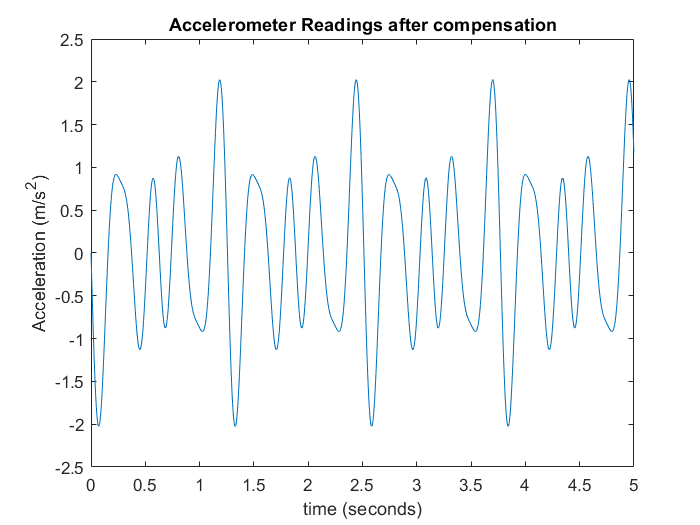


%gravity term is removed from resultant
Az_total = Az_x + Az_y + Az_z - g;

plot(t,Az_total)
title('Accelerometer Readings after compensation')
ylabel('Acceleration (m/s^2)') ;xlabel('time (seconds)')

az_trans = fft(Az_total);

**Significant frequency**

% significant frequency is where the maximum value
% of the frequency spectrum occurs 

maxSpec = max(abs(az_trans))

maxSpec = 2.4905e+03

y = abs(az_trans);
f  = 0:N-1;

%find where in the array the significant freqeuncy occurs
[f_sig,] = find(y==maxSpec) 

f_sig =           17
        4985



%find the first spectral component of the maximum
f_sig = min(f_sig)

f_sig = 17

**Detrending the data**

%detrended_AZ = detrend(az_trans);
detrended_AZ = az_trans;

**Filter design**

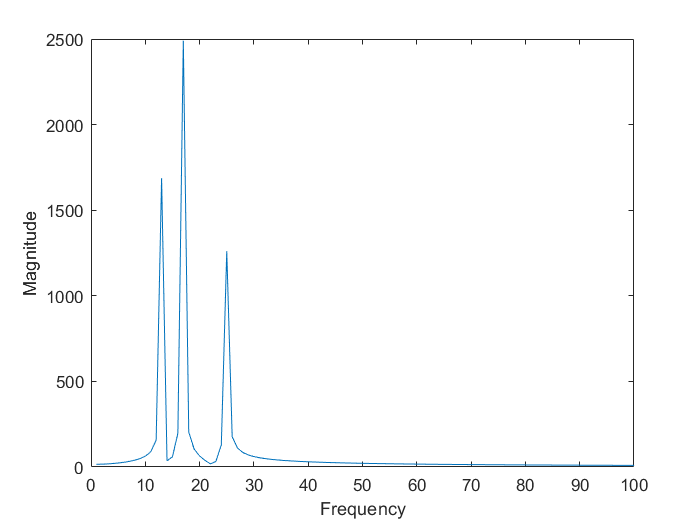

plot(abs(detrended_AZ));
xlim([0 100])
xlabel('Frequency'), ylabel('Magnitude')


size(detrended_AZ,2)

ans = 1

f1 = f_sig - 0.5*f_sig

f1 = 8.5000

f2 = f_sig + 0.5*f_sig

f2 = 25.5000


%fc_delta = 1/(2.*dt);

filtered_data = zeros(size(N));
L = 2*f_sig

L = 34


for i = 1:size(f,2)
    if f(i)<L
        fil = tukeywin(L,1.5);
        filtered_data(i) = fil(i).*detrended_AZ(i);
    else
        %fc_above = -1./(2*pi.*(f.^2));
        %filtered_data(i) = fc_above(i).*detrended_AZ(i);
        filtered_data(i) = 0;
    end
end

**Integration & wave height calculation**

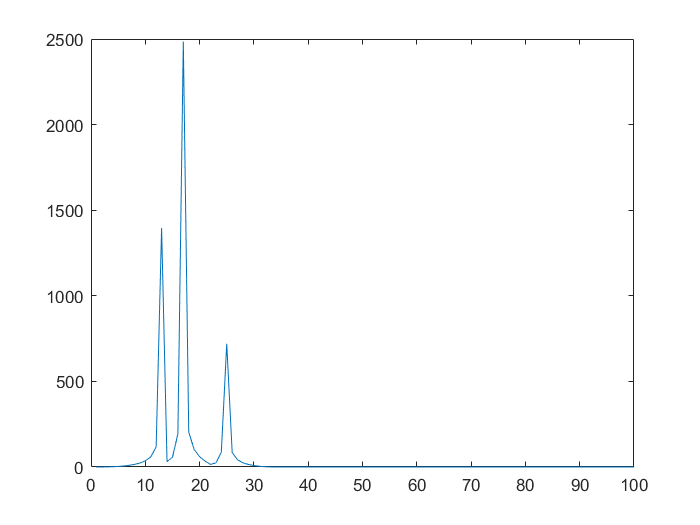

plot(abs(filtered_data));
xlim([0 100])


w = 2*pi.*fc

w = 125.6637

z = (-1./(w.^2)).*abs(filtered_data); 



PSD = 2.*(abs(z)).^2;

delta_f = f(2)-f(1);

% 
% for j = 1:size(z,2)
%     m0 = m0 + PSD(j);
% end

m0 = sum(PSD);
m0 = delta_f*m0;

hs = 4*sqrt(m0)

hs = 1.0613

Hs = 0.1*hs + hs

Hs = 1.1674

f_sig

f_sig = 17